# Figure 4

## vg3 trace

Rdom = 53

width = 11.7048

LIC: 89 peaks total, 65 corresponding RIC peaks.
RIC: 90 peaks total, 65 corresponding LIC peaks.
Mean RIC amplitude: 0.12108
Mean LIC amplitude: 0.15064
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-593-Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF


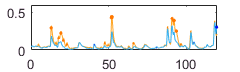


file = 'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-593-Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF.mat';
load(file);
[filePath name ext] = fileparts(file);
[stats, pkData] = findICpeaksdFoF(ICsignal,filePath,'dFoF',0);

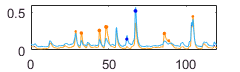


figSize = [5 5 2.5 0.75];
[m,n] = size(ICsignal);
smIC = smooth(ICsignal);
smIC = reshape(smIC,m,n);
lt_org = [255, 166 , 38]/255;
dk_org = [255, 120, 0]/255;
lt_blue = [50, 175, 242]/255;
dk_blue = [0, 13, 242]/255;
start = 2500;
endpt =start + 1200;
time = [1:1:(endpt-start+1)]'/10;
h = figure;
h.Units = 'inches';
h.Position = figSize;
hold off;
plot(time,smIC(start:endpt,1),'Color',lt_org);
hold on;
plot(time,smIC(start:endpt,2),'Color',lt_blue);
indices = find(pkdata(:,1) >= start & pkdata(:,1) <=endpt);
temp_pkData = pkdata(indices,:);
[m, n] = size(temp_pkData);
temp_pkData(:,[1 3]) = (temp_pkData(:,[1 3]) - [start*ones(m,1) start*ones(m,1)])/10;
r_pkData = temp_pkData(temp_pkData(:,7)==2,:);
l_pkData = temp_pkData(temp_pkData(:,7)==1,:);
scatter(r_pkData(:,3),r_pkData(:,4),r_pkData(:,5)*50,dk_blue,'filled');
scatter(l_pkData(:,1),l_pkData(:,2),l_pkData(:,5)*50,dk_org,'filled');
ylim([0 0.6]);
xlim([0 120]);

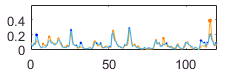


%WT traces
wtFile = 'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-330_processed\ICinfo16_dFoF.mat';
load('M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-330_processed\ICinfo16_dFoF.mat');
[m,n] = size(ICsignal);
smIC = smooth(ICsignal);
smIC = reshape(smIC,m,n);
lt_org = [255, 166 , 38]/255;
dk_org = [255, 120, 0]/255;
lt_blue = [50, 175, 242]/255;
dk_blue = [0, 13, 242]/255;
start = 3800;
endpt = 5000;
time = [1:1:(endpt-start+1)]'/10;
h = figure;
h.Units = 'inches';
h.Position = figSize;
hold off;
plot(time,smIC(start:endpt,1),'Color',lt_org);
hold on;
plot(time,smIC(start:endpt,2),'Color',lt_blue);
indices = find(pkData(:,1) >= start & pkData(:,1) <=endpt);
temp_pkData = pkData(indices,:);
[m, n] = size(temp_pkData);
temp_pkData(:,[1 3]) = (temp_pkData(:,[1 3]) - [start*ones(m,1) start*ones(m,1)])/10;
r_pkData = temp_pkData(temp_pkData(:,7)==2,:);
l_pkData = temp_pkData(temp_pkData(:,7)==1,:);
scatter(r_pkData(:,3),r_pkData(:,4),r_pkData(:,5)*50,dk_blue,'filled');
scatter(l_pkData(:,1),l_pkData(:,2),l_pkData(:,5)*50,dk_org,'filled');
ylim([-.01 0.6]);
xlim([0 120]);

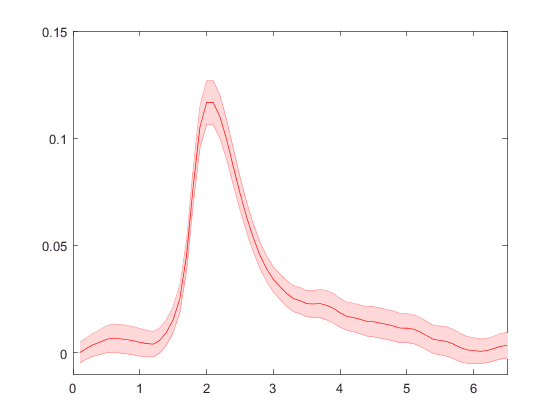


waveform({file});

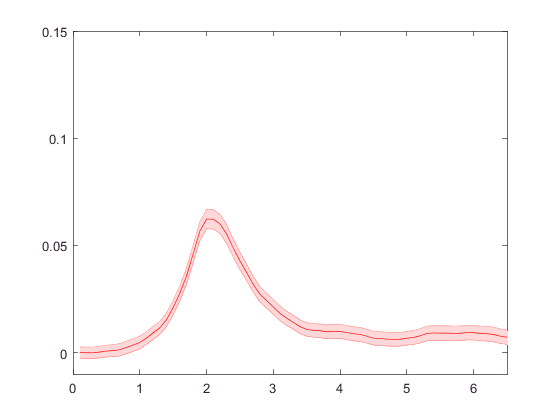

waveform({wtFile});

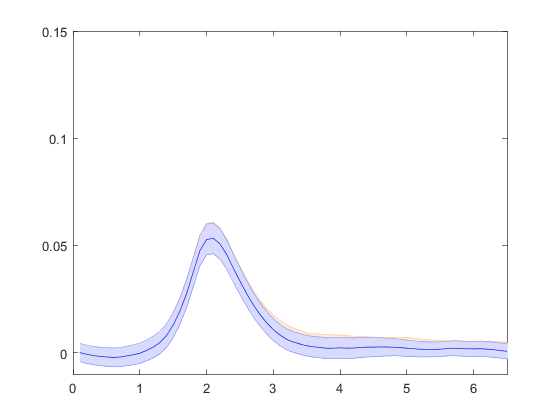

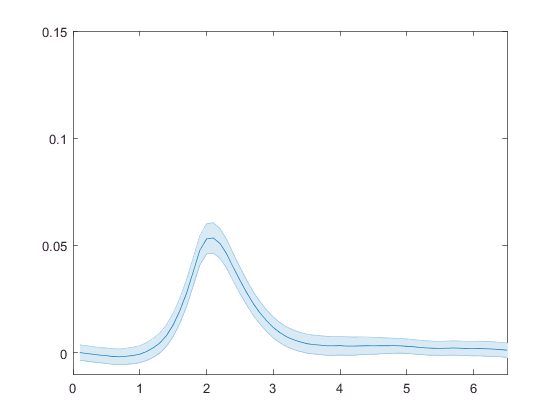


wt_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-265-P7_Wildtype_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-314-P6_Wildtype_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-330_processed\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-337-ds_PCApro\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-342_P2ry1het_ds.tif_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-495-P7-Snap25GC6s_Wildtype_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-569_P6-Snap25GC6s_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-571_P6-Snap25GC6s_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\Experiment-974_Snap25GC6s_vGluT3het\ICinfo16_dFoF.mat'
            };
        
vg3_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-496-P7-Snap25GC6s_vGluT3_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-545_P8_Snap25GC6s_vGluT3_matreg_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-593-Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-606_Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-607_Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-799_Snap25GC6s_vGluT3KO_reg\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\Experiment-974_Snap25GC6s_vGluT3KO\ICinfo16_dFoF.mat'};
         [avgWT, seWT] = waveform(wt_paths);

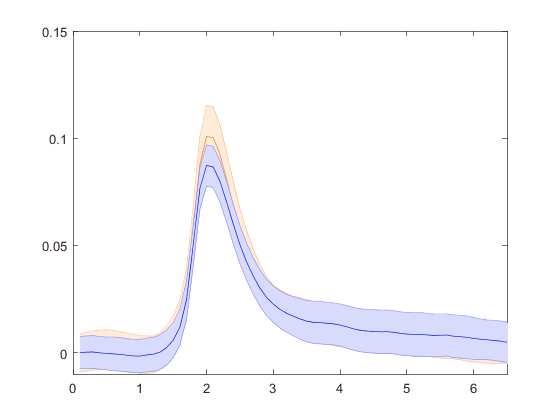

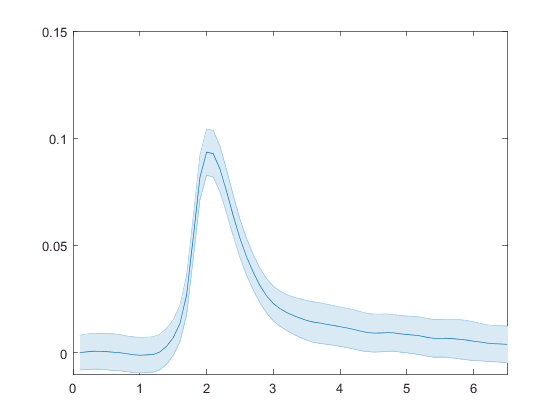

         [avgVG3, seVG3] = waveform(vg3_paths);

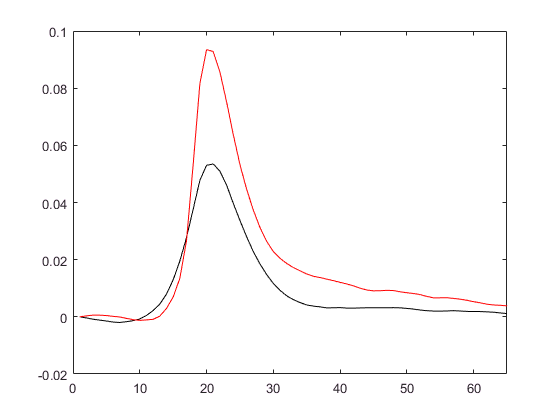

         h = figure;
         plot(avgWT,'k'); hold on;
         plot(avgVG3,'r');
         xlim([0 65]);

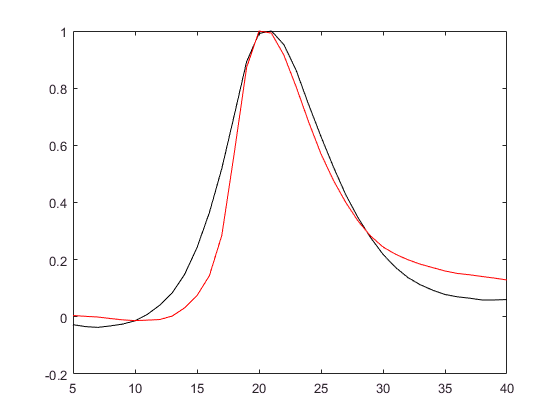

         h = figure;
         plot(avgWT/max(avgWT),'k'); hold on;
          plot(avgVG3/max(avgVG3),'r'); 
          xlim([5 40]);

binLim =          0    0.0200    0.0700    0.1200    0.1700    0.2200    0.2700    0.3200  100.0000


M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-265-P7_Wildtype_PCA\ICinfo16_dFoF.mat


Rdom = 70

width = 13.6854

LIC: 104 peaks total, 81 corresponding RIC peaks.
RIC: 104 peaks total, 81 corresponding LIC peaks.
Mean RIC amplitude: 0.04466
Mean LIC amplitude: 0.039644
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-265-P7_Wildtype_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-314-P6_Wildtype_PCA\ICinfo16_dFoF.mat


Rdom = 80

width = 13.1694

LIC: 130 peaks total, 88 corresponding RIC peaks.
RIC: 135 peaks total, 88 corresponding LIC peaks.
Mean RIC amplitude: 0.096619
Mean LIC amplitude: 0.10346
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-314-P6_Wildtype_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-330_processed\ICinfo16_dFoF.mat


Rdom = 90

width = 14.9592

LIC: 136 peaks total, 91 corresponding RIC peaks.
RIC: 129 peaks total, 91 corresponding LIC peaks.
Mean RIC amplitude: 0.087649
Mean LIC amplitude: 0.08572
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-330_processed\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-337-ds_PCApro\ICinfo16_dFoF.mat


Rdom = 106

width = 13.3357

LIC: 141 peaks total, 106 corresponding RIC peaks.
RIC: 148 peaks total, 106 corresponding LIC peaks.
Mean RIC amplitude: 0.071521
Mean LIC amplitude: 0.06676
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-337-ds_PCApro\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-342_P2ry1het_ds.tif_PCA\ICinfo16_dFoF.mat


Rdom = 86

width = 12.4352

LIC: 132 peaks total, 100 corresponding RIC peaks.
RIC: 140 peaks total, 100 corresponding LIC peaks.
Mean RIC amplitude: 0.050038
Mean LIC amplitude: 0.0507
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-342_P2ry1het_ds.tif_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-495-P7-Snap25GC6s_Wildtype_PCA\ICinfo16_dFoF.mat


Rdom = 104

width = 13.0947

LIC: 141 peaks total, 92 corresponding RIC peaks.
RIC: 143 peaks total, 92 corresponding LIC peaks.
Mean RIC amplitude: 0.068904
Mean LIC amplitude: 0.065379
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-495-P7-Snap25GC6s_Wildtype_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-569_P6-Snap25GC6s_PCA\ICinfo16_dFoF.mat


Rdom = 90

width = 13.6029

LIC: 131 peaks total, 105 corresponding RIC peaks.
RIC: 134 peaks total, 105 corresponding LIC peaks.
Mean RIC amplitude: 0.098175
Mean LIC amplitude: 0.092054
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-569_P6-Snap25GC6s_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-571_P6-Snap25GC6s_PCA\ICinfo16_dFoF.mat


Rdom = 81

width = 15.6521

LIC: 121 peaks total, 84 corresponding RIC peaks.
RIC: 124 peaks total, 84 corresponding LIC peaks.
Mean RIC amplitude: 0.099862
Mean LIC amplitude: 0.099719
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-571_P6-Snap25GC6s_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\Experiment-974_Snap25GC6s_vGluT3het\ICinfo16_dFoF.mat


Rdom = 80

width = 19.9602

LIC: 98 peaks total, 59 corresponding RIC peaks.
RIC: 108 peaks total, 59 corresponding LIC peaks.
Mean RIC amplitude: 0.085431
Mean LIC amplitude: 0.076859
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\Experiment-974_Snap25GC6s_vGluT3het\ICinfo16_dFoF


m = 9

rCounts =     24    57    12     8     3     0     0     0


rCounts =      2    39    36    34    15     6     3     0


rCounts =      7    41    42    18     9    10     1     1


rCounts =      8    67    42    22     7     2     0     0


rCounts =     15    88    29     5     2     1     0     0


rCounts =      9    68    34    17    11     4     0     0


rCounts =      8    45    32    19    15    12     2     1


rCounts =     10    34    32    25    11     7     5     0


rCounts =      8    35    31    18    10     4     0     2


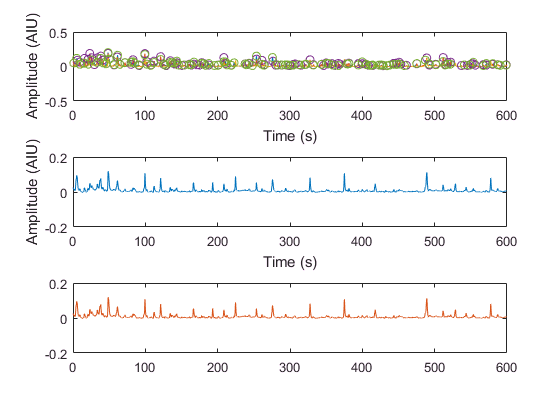

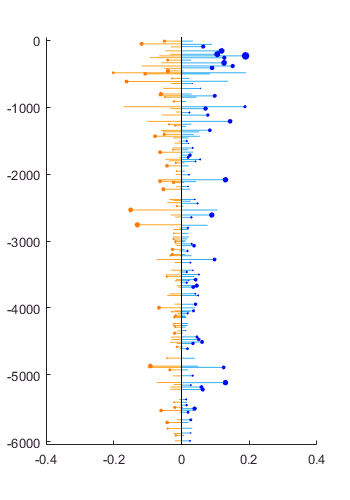

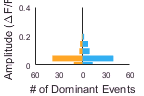

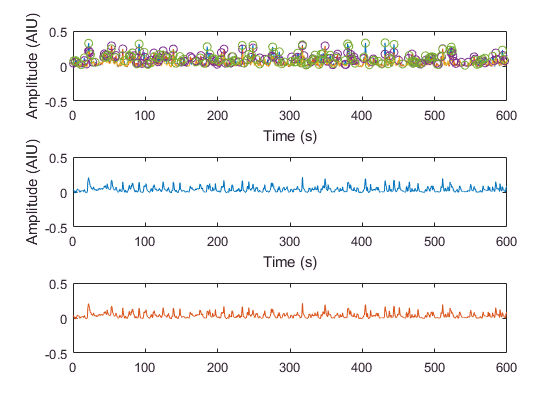

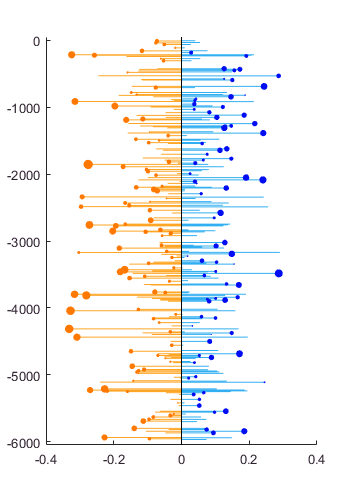

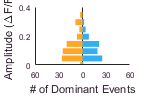

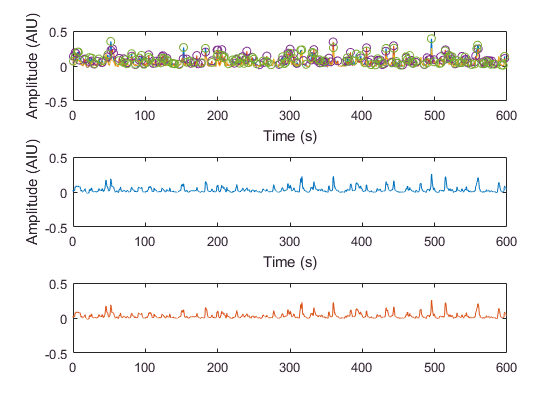

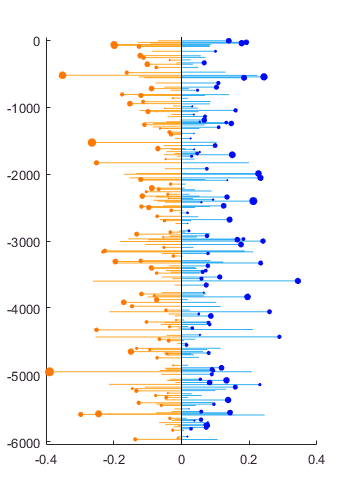

          
WTdata = groupData(wt_paths,16);

## Average waveforms and stats

r_locs =     93
   158
   208
   232
   261
   336
   384
   412
   646
   720


r_locs =    183
   233
   424
   433
   449
   532
   576
   593
   688
   821


r_locs =      7
    29
    42
   164
   337
   546
   560
   638
   700
   746


r_locs =     50
    97
   263
   290
   312
   417
   476
   504
   634
   708


r_locs =     98
   159
   334
   364
   429
   670
   705
   789
   815
   828


r_locs =     14
   123
   135
   179
   216
   388
   429
   468
   496
   527


r_locs =     73
   185
   229
   291
   322
   368
   388
   479
   573
   649


r_locs =    180
   218
   409
   432
   465
   496
   582
   632
   660
   681


r_locs =    371
   405
   473
   496
   577
   616
   636
   651
   843
   949


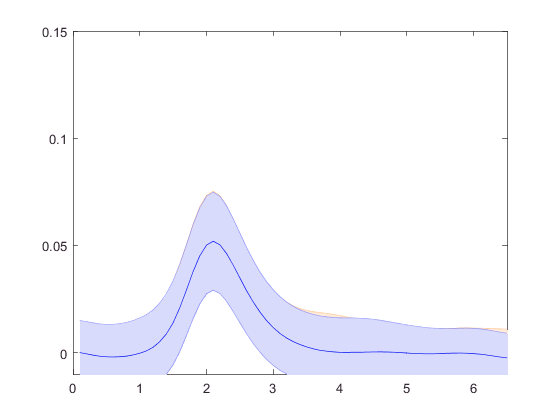

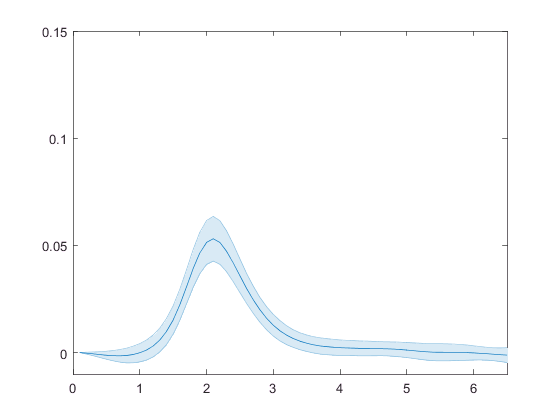

wt_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-265-P7_Wildtype_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-314-P6_Wildtype_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-330_processed\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-337-ds_PCApro\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-342_P2ry1het_ds.tif_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-495-P7-Snap25GC6s_Wildtype_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-569_P6-Snap25GC6s_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-571_P6-Snap25GC6s_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\Experiment-974_Snap25GC6s_vGluT3het\ICinfo16_dFoF.mat'
            };
        
vg3_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-496-P7-Snap25GC6s_vGluT3_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-545_P8_Snap25GC6s_vGluT3_matreg_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-593-Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-606_Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-607_Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-799_Snap25GC6s_vGluT3KO_reg\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\Experiment-974_Snap25GC6s_vGluT3KO\ICinfo16_dFoF.mat'};
         [avgWT, seWT] = waveform2(wt_paths);

r_locs =          232
         273
         418
         588
         718
         746
         836
         866
         956
        1036


r_locs =          219
         472
         648
         719
         754
         847
        1125
        1256
        1320
        1346


r_locs =           80
         253
         466
         597
         622
         723
         845
         890
         989
        1407


r_locs =           98
         131
         450
         506
         530
         596
         696
         766
        1032
        1072


r_locs =          189
         258
         417
         568
         714
         790
        1088
        1132
        1697
        1716


r_locs =     75
   232
   515
   552
   597
   806
   830
   871
   899
   938


r_locs =      9
    82
   109
   123
   195
   455
   539
   630
   752
   771


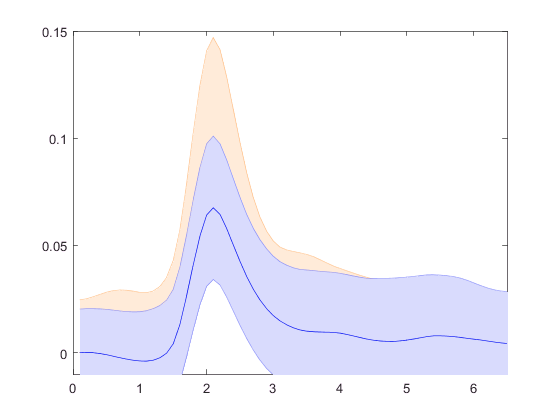

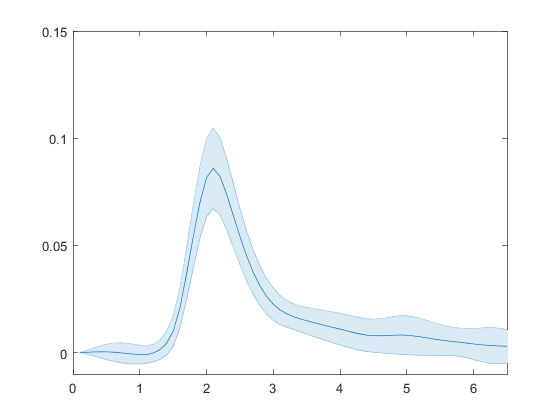

         [avgVG3, seVG3] = waveform2(vg3_paths);

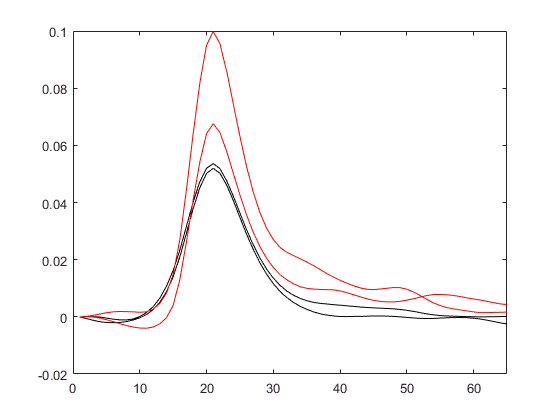

         h = figure;
         plot(avgWT,'k'); hold on;
         plot(avgVG3,'r');
         xlim([0 65]);

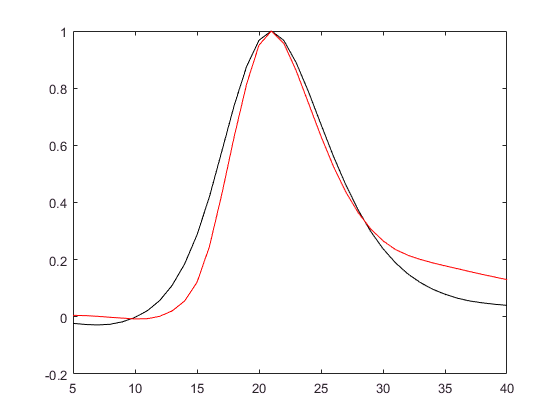

         h = figure;
         plot(avgWT/max(avgWT),'k'); hold on;
         plot(avgVG3/max(avgVG3),'r'); 
         xlim([5 40]);

## stats plot

binLim =          0    0.0200    0.0700    0.1200    0.1700    0.2200    0.2700    0.3200  100.0000


M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-265-P7_Wildtype_PCA\ICinfo16_dFoF.mat


Rdom = 70

width = 13.6854

tempPkData =    12.0000    0.0503   12.0000    0.0335    0.0168    2.0000    1.0000
   52.0000    0.1178   60.0000    0.0900    0.0279    1.0000    1.0000
  295.0000    0.0410  295.0000    0.0280    0.0130    3.0000    1.0000
  457.0000    0.0399  457.0000    0.0061    0.0338    2.0000    1.0000
  485.0000    0.2015  485.0000    0.1901    0.0114    1.0000    1.0000
  501.0000    0.1072  501.0000    0.0842    0.0229    2.0000    1.0000
  569.0000    0.0282  569.0000    0.0230    0.0051    1.0000    1.0000
  616.0000    0.1621  612.0000    0.1373    0.0249    1.0000    1.0000
  802.0000    0.0608  802.0000    0.0303    0.0305    1.0000    1.0000
  851.0000    0.0490  851.0000    0.0439    0.0051    2.0000    1.0000


LIC: 104 peaks total, 81 corresponding RIC peaks.
RIC: 104 peaks total, 81 corresponding LIC peaks.
Mean RIC amplitude: 0.04466
Mean LIC amplitude: 0.039644
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-265-P7_Wildtype_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-314-P6_Wildtype_PCA\ICinfo16_dFoF.mat


Rdom = 80

width = 13.1694

tempPkData =    10.0000    0.0726    7.0000    0.0407    0.0319    1.0000    1.0000
   37.0000    0.0755   33.0000    0.0547    0.0208    1.0000    1.0000
   62.0000    0.0508   62.0000    0.0278    0.0230    2.0000    1.0000
  112.0000    0.0184  112.0000    0.0097    0.0088    2.0000    1.0000
  157.0000    0.1165  156.0000    0.0766    0.0399    1.0000    1.0000
  216.0000    0.3243  215.0000    0.2139    0.1105    1.0000    1.0000
  223.0000    0.2571  223.0000    0.2071    0.0500    3.0000    1.0000
  273.0000    0.0609  273.0000    0.0552    0.0057    3.0000    1.0000
  305.0000    0.0529  305.0000    0.0294    0.0235    2.0000    1.0000
  479.0000    0.1590  472.0000    0.1493    0.0098    1.0000    1.0000


LIC: 130 peaks total, 88 corresponding RIC peaks.
RIC: 135 peaks total, 88 corresponding LIC peaks.
Mean RIC amplitude: 0.096619
Mean LIC amplitude: 0.10346
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-314-P6_Wildtype_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-330_processed\ICinfo16_dFoF.mat


Rdom = 90

width = 14.9592

tempPkData =    63.0000    0.1993   63.0000    0.0868    0.1125    2.0000    1.0000
   75.0000    0.1983   75.0000    0.0821    0.1162    2.0000    1.0000
   92.0000    0.1256   92.0000    0.0841    0.0415    3.0000    1.0000
  229.0000    0.1218  231.0000    0.0569    0.0649    1.0000    1.0000
  258.0000    0.1123  255.0000    0.0713    0.0411    1.0000    1.0000
  295.0000    0.0348  292.0000    0.0264    0.0084    1.0000    1.0000
  357.0000    0.1009  357.0000    0.0337    0.0672    2.0000    1.0000
  405.0000    0.0745  404.0000    0.0494    0.0251    1.0000    1.0000
  482.0000    0.1616  476.0000    0.1302    0.0314    1.0000    1.0000
  522.0000    0.3512  524.0000    0.2238    0.1274    1.0000    1.0000


LIC: 136 peaks total, 91 corresponding RIC peaks.
RIC: 129 peaks total, 91 corresponding LIC peaks.
Mean RIC amplitude: 0.087649
Mean LIC amplitude: 0.08572
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-330_processed\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-337-ds_PCApro\ICinfo16_dFoF.mat


Rdom = 106

width = 13.3357

tempPkData =     2.0000    0.2991    2.0000    0.1434    0.1558    2.0000    1.0000
   31.0000    0.1308   31.0000    0.0660    0.0648    2.0000    1.0000
  213.0000    0.0287  215.0000    0.0253    0.0034    1.0000    1.0000
  240.0000    0.1335  239.0000    0.0463    0.0873    1.0000    1.0000
  360.0000    0.0455  360.0000    0.0149    0.0306    2.0000    1.0000
  517.0000    0.0509  517.0000    0.0168    0.0341    2.0000    1.0000
  550.0000    0.1748  550.0000    0.0624    0.1125    1.0000    1.0000
  577.0000    0.0688  579.0000    0.0534    0.0153    1.0000    1.0000
  617.0000    0.0197  617.0000   -0.0002    0.0199    2.0000    1.0000
  751.0000    0.1221  751.0000    0.0540    0.0681    2.0000    1.0000


LIC: 141 peaks total, 106 corresponding RIC peaks.
RIC: 148 peaks total, 106 corresponding LIC peaks.
Mean RIC amplitude: 0.071521
Mean LIC amplitude: 0.06676
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-337-ds_PCApro\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-342_P2ry1het_ds.tif_PCA\ICinfo16_dFoF.mat


Rdom = 86

width = 12.4352

tempPkData =    26.0000    0.0299   25.0000    0.0274    0.0025    1.0000    1.0000
  228.0000    0.1440  226.0000    0.0971    0.0469    1.0000    1.0000
  261.0000    0.2709  259.0000    0.1896    0.0813    1.0000    1.0000
  398.0000    0.0812  399.0000    0.0791    0.0021    1.0000    1.0000
  449.0000    0.0392  448.0000    0.0338    0.0054    1.0000    1.0000
  472.0000    0.0714  471.0000    0.0513    0.0201    1.0000    1.0000
  487.0000    0.0886  487.0000    0.0361    0.0525    2.0000    1.0000
  506.0000    0.0336  506.0000    0.0093    0.0243    2.0000    1.0000
  554.0000    0.0266  550.0000    0.0266    0.0000    1.0000    1.0000
  572.0000    0.0579  572.0000    0.0472    0.0107    1.0000    1.0000


LIC: 132 peaks total, 100 corresponding RIC peaks.
RIC: 140 peaks total, 100 corresponding LIC peaks.
Mean RIC amplitude: 0.050038
Mean LIC amplitude: 0.0507
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-342_P2ry1het_ds.tif_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-495-P7-Snap25GC6s_Wildtype_PCA\ICinfo16_dFoF.mat


Rdom = 104

width = 13.0947

tempPkData =    47.0000    0.0808   47.0000    0.0037    0.0771    2.0000    1.0000
   89.0000    0.0668   89.0000    0.0065    0.0603    2.0000    1.0000
  245.0000    0.1285  245.0000    0.0373    0.0912    2.0000    1.0000
  289.0000    0.1536  287.0000    0.0800    0.0736    1.0000    1.0000
  304.0000    0.0857  304.0000    0.0578    0.0279    3.0000    1.0000
  347.0000    0.0248  352.0000    0.0193    0.0055    1.0000    1.0000
  564.0000    0.0490  564.0000    0.0304    0.0186    2.0000    1.0000
  584.0000    0.1573  584.0000    0.0721    0.0852    2.0000    1.0000
  600.0000    0.1408  598.0000    0.1140    0.0268    1.0000    1.0000
  773.0000    0.1389  773.0000    0.0283    0.1106    2.0000    1.0000


LIC: 141 peaks total, 92 corresponding RIC peaks.
RIC: 143 peaks total, 92 corresponding LIC peaks.
Mean RIC amplitude: 0.068904
Mean LIC amplitude: 0.065379
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-495-P7-Snap25GC6s_Wildtype_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-569_P6-Snap25GC6s_PCA\ICinfo16_dFoF.mat


Rdom = 90

width = 13.6029

tempPkData =    30.0000    0.0212   30.0000    0.0161    0.0051    3.0000    1.0000
  125.0000    0.0906  124.0000    0.0415    0.0492    1.0000    1.0000
  244.0000    0.2214  241.0000    0.1898    0.0317    1.0000    1.0000
  303.0000    0.0157  303.0000    0.0027    0.0129    2.0000    1.0000
  507.0000    0.0294  507.0000    0.0233    0.0061    2.0000    1.0000
  542.0000    0.1622  541.0000    0.1341    0.0281    1.0000    1.0000
  622.0000    0.0829  622.0000    0.0445    0.0384    1.0000    1.0000
  692.0000    0.0193  688.0000    0.0176    0.0017    1.0000    1.0000
  788.0000    0.0273  788.0000    0.0186    0.0087    2.0000    1.0000
  805.0000    0.0850  803.0000    0.0838    0.0012    1.0000    1.0000


LIC: 131 peaks total, 105 corresponding RIC peaks.
RIC: 134 peaks total, 105 corresponding LIC peaks.
Mean RIC amplitude: 0.098175
Mean LIC amplitude: 0.092054
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-569_P6-Snap25GC6s_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-571_P6-Snap25GC6s_PCA\ICinfo16_dFoF.mat


Rdom = 81

width = 15.6521

tempPkData =    46.0000    0.0294   46.0000    0.0230    0.0064    3.0000    1.0000
   65.0000    0.0893   68.0000    0.0609    0.0285    1.0000    1.0000
  121.0000    0.1008  121.0000    0.0898    0.0110    1.0000    1.0000
  351.0000    0.1219  361.0000    0.1028    0.0191    1.0000    1.0000
  510.0000    0.0901  510.0000    0.0810    0.0091    2.0000    1.0000
  535.0000    0.0964  535.0000    0.0328    0.0636    2.0000    1.0000
  617.0000    0.0696  617.0000    0.0508    0.0187    2.0000    1.0000
  704.0000    0.0711  704.0000    0.0400    0.0311    2.0000    1.0000
  736.0000    0.0968  726.0000    0.0753    0.0215    1.0000    1.0000
  766.0000    0.0328  766.0000    0.0208    0.0120    2.0000    1.0000


LIC: 121 peaks total, 84 corresponding RIC peaks.
RIC: 124 peaks total, 84 corresponding LIC peaks.
Mean RIC amplitude: 0.099862
Mean LIC amplitude: 0.099719
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-571_P6-Snap25GC6s_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\Experiment-974_Snap25GC6s_vGluT3het\ICinfo16_dFoF.mat


Rdom = 80

width = 19.9602

tempPkData =     8.0000    0.0559    8.0000    0.0405    0.0154    2.0000    1.0000
   49.0000    0.0343   49.0000    0.0115    0.0229    2.0000    1.0000
  106.0000    0.0369  106.0000    0.0318    0.0052    2.0000    1.0000
  152.0000    0.0553  152.0000    0.0274    0.0279    2.0000    1.0000
  223.0000    0.1323  219.0000    0.0991    0.0332    1.0000    1.0000
  294.0000    0.1488  294.0000    0.0945    0.0543    2.0000    1.0000
  517.0000    0.0505  526.0000    0.0380    0.0125    1.0000    1.0000
  774.0000    0.0388  774.0000    0.0077    0.0311    2.0000    1.0000
  787.0000    0.0352  787.0000    0.0272    0.0080    3.0000    1.0000
  863.0000    0.0544  863.0000    0.0274    0.0270    2.0000    1.0000


LIC: 98 peaks total, 59 corresponding RIC peaks.
RIC: 108 peaks total, 59 corresponding LIC peaks.
Mean RIC amplitude: 0.085431
Mean LIC amplitude: 0.076859
M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\Experiment-974_Snap25GC6s_vGluT3het\ICinfo16_dFoF
delta


delta =     0.6603    0.6746    0.6459    0.6528    0.6408    0.5760    0.7106    0.7086    0.5664


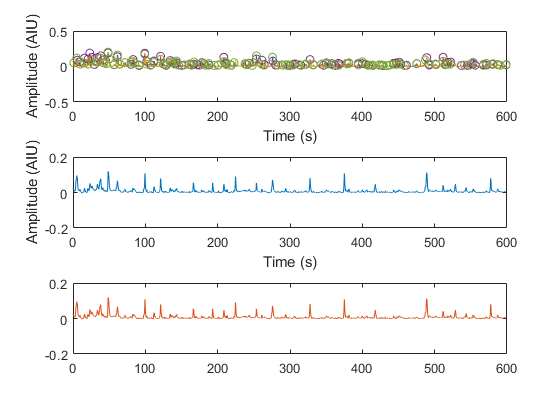

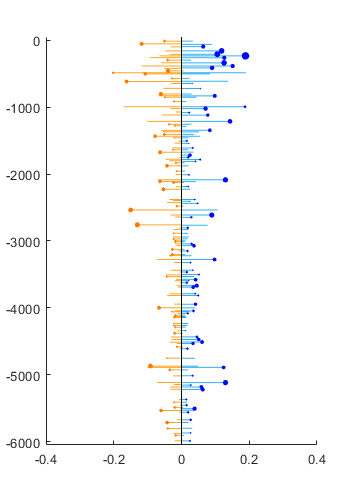

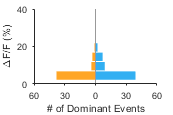

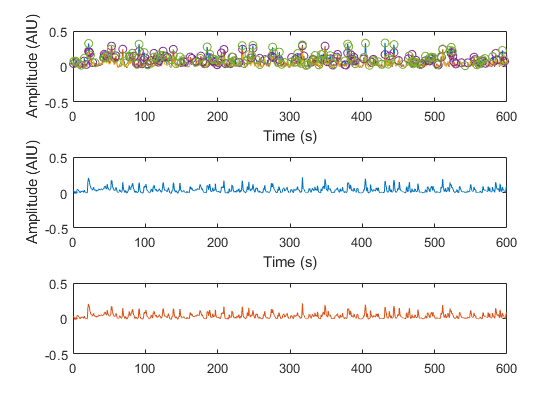

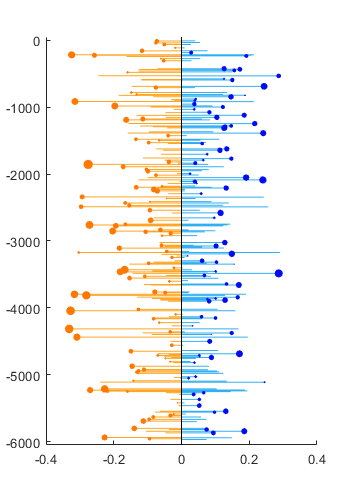

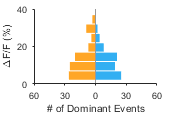

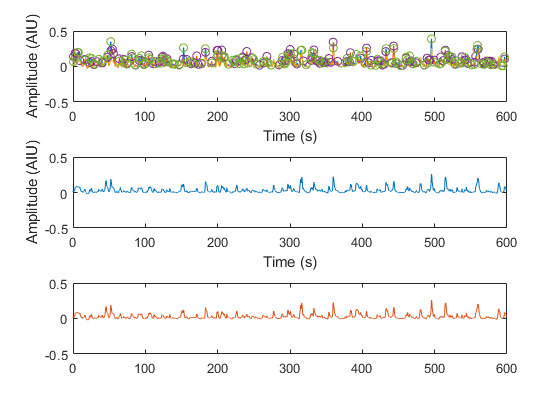

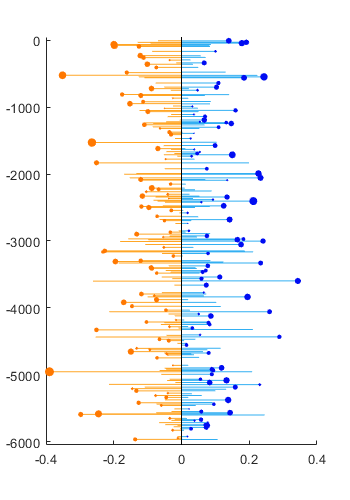


 WTdata = groupData(wt_paths,16);

binLim =          0    0.0200    0.0700    0.1200    0.1700    0.2200    0.2700    0.3200  100.0000


M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-496-P7-Snap25GC6s_vGluT3_PCA\ICinfo16_dFoF.mat


Rdom = 51

width = 9.6274

tempPkData =   139.0000    0.1450  139.0000    0.1241    0.0209    1.0000    1.0000
  184.0000    0.6523  184.0000    0.3224    0.3299    1.0000    1.0000
  196.0000    0.6313  196.0000    0.3256    0.3057    1.0000    1.0000
  210.0000    0.3487  210.0000    0.1501    0.1986    2.0000    1.0000
  246.0000    0.2046  246.0000    0.1071    0.0974    2.0000    1.0000
  374.0000    0.0408  374.0000    0.0252    0.0156    2.0000    1.0000
  406.0000    0.0613  406.0000    0.0421    0.0192    2.0000    1.0000
  462.0000    0.0961  462.0000    0.0936    0.0025    1.0000    1.0000
  500.0000    0.0197  500.0000    0.0065    0.0133    2.0000    1.0000
  517.0000    0.1076  517.0000    0.0828    0.0248    1.0000    1.0000


LIC: 89 peaks total, 69 corresponding RIC peaks.
RIC: 107 peaks total, 69 corresponding LIC peaks.
Mean RIC amplitude: 0.102
Mean LIC amplitude: 0.1499
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-496-P7-Snap25GC6s_vGluT3_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-545_P8_Snap25GC6s_vGluT3_matreg_PCA\ICinfo16_dFoF.mat


Rdom = 51

width = 10.8787

tempPkData =     4.0000    0.0797    4.0000    0.0581    0.0215    2.0000    1.0000
   79.0000    0.0470   79.0000    0.0285    0.0185    1.0000    1.0000
  248.0000    0.1053  239.0000    0.0677    0.0377    1.0000    1.0000
  543.0000    0.1131  543.0000    0.0723    0.0408    1.0000    1.0000
  601.0000    0.0400  601.0000    0.0191    0.0209    2.0000    1.0000
  677.0000    0.0739  677.0000    0.0459    0.0281    2.0000    1.0000
  782.0000    0.0467  782.0000    0.0401    0.0066    2.0000    1.0000
  810.0000    0.0897  810.0000    0.0470    0.0427    2.0000    1.0000
  836.0000    0.0509  836.0000    0.0366    0.0142    1.0000    1.0000
  935.0000    0.1093  935.0000    0.0636    0.0457    2.0000    1.0000


LIC: 74 peaks total, 47 corresponding RIC peaks.
RIC: 70 peaks total, 47 corresponding LIC peaks.
Mean RIC amplitude: 0.089081
Mean LIC amplitude: 0.088716
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-545_P8_Snap25GC6s_vGluT3_matreg_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-593-Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF.mat


Rdom = 53

width = 11.7048

tempPkData =   154.0000    0.1329  156.0000    0.0816    0.0513    1.0000    1.0000
  191.0000    0.0799  191.0000    0.0218    0.0581    2.0000    1.0000
  312.0000    0.2893  312.0000    0.1184    0.1709    1.0000    1.0000
  324.0000    0.2814  324.0000    0.0891    0.1923    2.0000    1.0000
  339.0000    0.1481  339.0000    0.0507    0.0974    2.0000    1.0000
  356.0000    0.0802  356.0000    0.0583    0.0219    2.0000    1.0000
  433.0000    0.2770  433.0000    0.2419    0.0352    1.0000    1.0000
  673.0000    0.1357  680.0000    0.0337    0.1020    1.0000    1.0000
  693.0000    0.3047  693.0000    0.1159    0.1888    1.0000    1.0000
  705.0000    0.1230  705.0000    0.0853    0.0376    3.0000    1.0000


LIC: 89 peaks total, 65 corresponding RIC peaks.
RIC: 90 peaks total, 65 corresponding LIC peaks.
Mean RIC amplitude: 0.12108
Mean LIC amplitude: 0.15064
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-593-Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-606_Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF.mat


Rdom = 59

width = 11.7717

tempPkData =    14.0000    0.0579   13.0000    0.0462    0.0117    1.0000    1.0000
  159.0000    0.1138  150.0000    0.0902    0.0235    1.0000    1.0000
  160.0000    0.1092  160.0000    0.0876    0.0216    3.0000    1.0000
  171.0000    0.1116  170.0000    0.1082    0.0034    1.0000    1.0000
  256.0000    0.0446  256.0000    0.0342    0.0104    1.0000    1.0000
  325.0000    0.0222  325.0000    0.0147    0.0075    2.0000    1.0000
  432.0000    0.0874  424.0000    0.0841    0.0034    1.0000    1.0000
  639.0000    0.0902  639.0000    0.0540    0.0362    1.0000    1.0000
  728.0000    0.3572  728.0000    0.2720    0.0852    1.0000    1.0000
  777.0000    0.0790  777.0000    0.0172    0.0618    2.0000    1.0000


LIC: 93 peaks total, 67 corresponding RIC peaks.
RIC: 99 peaks total, 67 corresponding LIC peaks.
Mean RIC amplitude: 0.088494
Mean LIC amplitude: 0.092112
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-606_Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-607_Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF.mat


Rdom = 39

width = 10.7684

tempPkData =    1.0e+03 *

    0.2270    0.0000    0.2270    0.0000    0.0000    0.0020    0.0010
    0.3720    0.0000    0.3720    0.0000    0.0000    0.0020    0.0010
    0.4810    0.0000    0.4820    0.0000    0.0000    0.0010    0.0010
    0.6020    0.0001    0.6010    0.0001    0.0000    0.0010    0.0010
    0.7450    0.0001    0.7440    0.0001    0.0000    0.0010    0.0010
    0.8980    0.0000    0.8980    0.0000    0.0000    0.0020    0.0010
    1.0030    0.0005    1.0030    0.0005    0.0000    0.0010    0.0010
    1.1110    0.0000    1.1110    0.0000    0.0000    0.0020    0.0010
    1.1510    0.0000    1.1510    0.0000    0.0000    0.0020    0.0010
    1.1750    0.0000    1.1750    0.0000    0.0000    0.0010    0.0010


LIC: 77 peaks total, 62 corresponding RIC peaks.
RIC: 72 peaks total, 62 corresponding LIC peaks.
Mean RIC amplitude: 0.092626
Mean LIC amplitude: 0.094947
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-607_Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-799_Snap25GC6s_vGluT3KO_reg\ICinfo16_dFoF.mat


Rdom = 89

width = 10.5711

tempPkData =    1.0e+03 *

    0.4760    0.0000    0.4760    0.0000    0.0000    0.0020    0.0010
    0.5260    0.0000    0.5260    0.0000    0.0000    0.0020    0.0010
    0.6450    0.0001    0.6520    0.0000    0.0000    0.0010    0.0010
    0.6680    0.0000    0.6680    0.0000    0.0000    0.0020    0.0010
    0.7140    0.0001    0.7140    0.0001    0.0001    0.0020    0.0010
    0.7900    0.0000    0.7900    0.0000    0.0000    0.0020    0.0010
    0.8440    0.0001    0.8440    0.0001    0.0000    0.0010    0.0010
    0.8610    0.0001    0.8620    0.0001    0.0000    0.0010    0.0010
    0.9860    0.0001    0.9960    0.0001    0.0000    0.0010    0.0010
    1.0130    0.0000    1.0130    0.0000    0.0000    0.0020    0.0010


LIC: 133 peaks total, 103 corresponding RIC peaks.
RIC: 136 peaks total, 103 corresponding LIC peaks.
Mean RIC amplitude: 0.1021
Mean LIC amplitude: 0.10323
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-799_Snap25GC6s_vGluT3KO_reg\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\Experiment-974_Snap25GC6s_vGluT3KO\ICinfo16_dFoF.mat


Rdom = 97

width = 11.7944

tempPkData =    48.0000    0.1880   55.0000    0.1649    0.0231    1.0000    1.0000
   73.0000    0.2180   68.0000    0.1907    0.0273    1.0000    1.0000
  181.0000    0.0264  181.0000    0.0208    0.0056    1.0000    1.0000
  240.0000    0.2060  240.0000    0.1906    0.0155    1.0000    1.0000
  263.0000    0.1750  263.0000    0.1547    0.0203    1.0000    1.0000
  293.0000    0.0605  292.0000    0.0491    0.0115    1.0000    1.0000
  323.0000    0.1611  323.0000    0.0964    0.0647    2.0000    1.0000
  349.0000    0.1306  353.0000    0.0689    0.0617    1.0000    1.0000
  365.0000    0.2445  365.0000    0.2175    0.0271    1.0000    1.0000
  374.0000    0.2416  374.0000    0.1446    0.0970    2.0000    1.0000


LIC: 172 peaks total, 129 corresponding RIC peaks.
RIC: 166 peaks total, 129 corresponding LIC peaks.
Mean RIC amplitude: 0.16513
Mean LIC amplitude: 0.1679
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\Experiment-974_Snap25GC6s_vGluT3KO\ICinfo16_dFoF
delta


delta =     0.5718    0.7763    0.6065    0.6774    0.7821    0.7262    0.7723


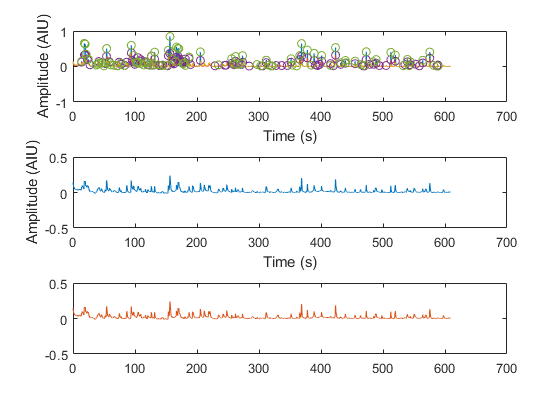

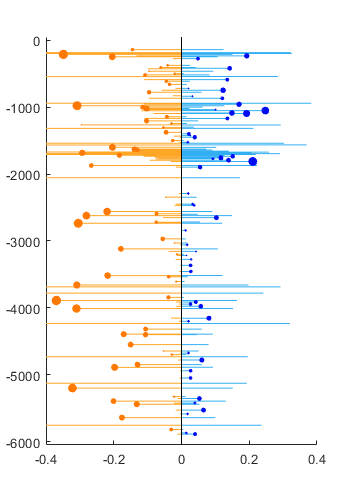

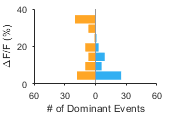

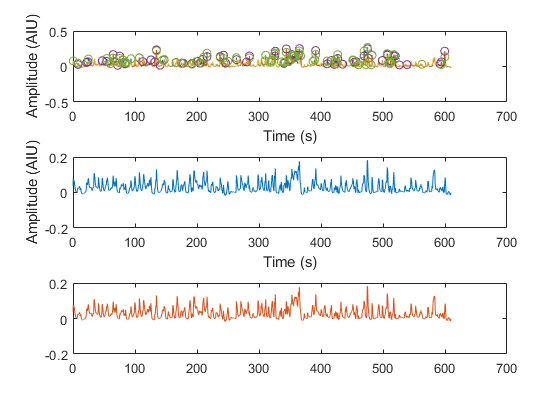

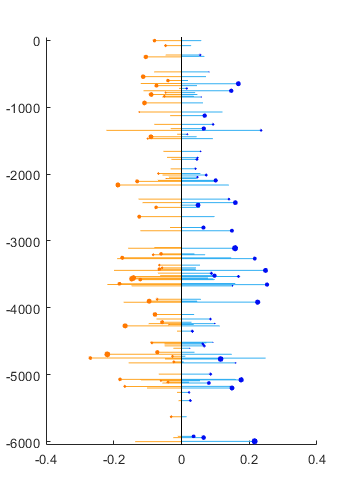

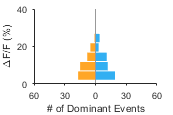

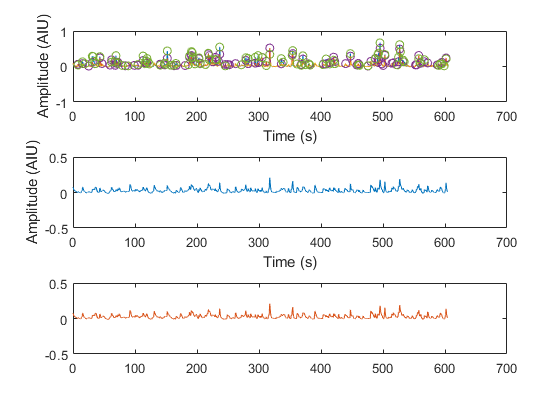

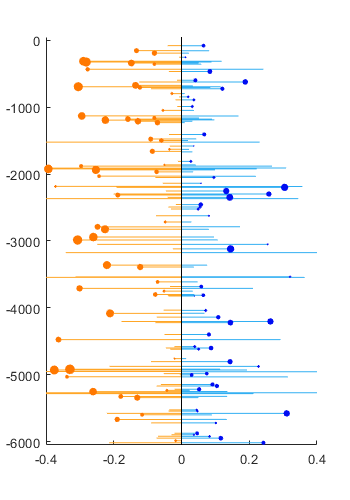

 VG3data = groupData(vg3_paths,16);

r_locs =     93
   158
   208
   232
   261
   336
   384
   412
   646
   720


r_locs =    183
   233
   424
   433
   449
   532
   576
   593
   688
   821


r_locs =      7
    29
    42
   164
   337
   546
   560
   638
   700
   746


r_locs =     50
    97
   263
   290
   312
   417
   476
   504
   634
   708


r_locs =     98
   159
   334
   364
   429
   670
   705
   789
   815
   828


r_locs =     14
   123
   135
   179
   216
   388
   429
   468
   496
   527


r_locs =     73
   185
   229
   291
   322
   368
   388
   479
   573
   649


r_locs =    180
   218
   409
   432
   465
   496
   582
   632
   660
   681


r_locs =    371
   405
   473
   496
   577
   616
   636
   651
   843
   949


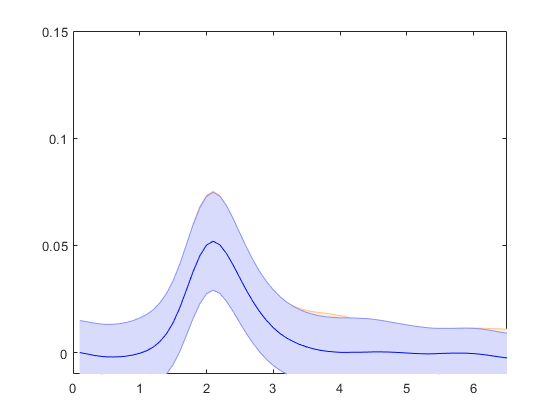

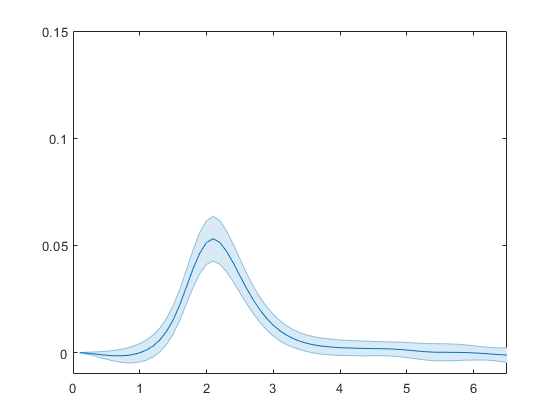

[avg, se, hw, ampl] = waveform2(wt_paths);

r_locs =          232
         273
         418
         588
         718
         746
         836
         866
         956
        1036


r_locs =          219
         472
         648
         719
         754
         847
        1125
        1256
        1320
        1346


r_locs =           80
         253
         466
         597
         622
         723
         845
         890
         989
        1407


r_locs =           98
         131
         450
         506
         530
         596
         696
         766
        1032
        1072


r_locs =          189
         258
         417
         568
         714
         790
        1088
        1132
        1697
        1716


r_locs =     75
   232
   515
   552
   597
   806
   830
   871
   899
   938


r_locs =      9
    82
   109
   123
   195
   455
   539
   630
   752
   771


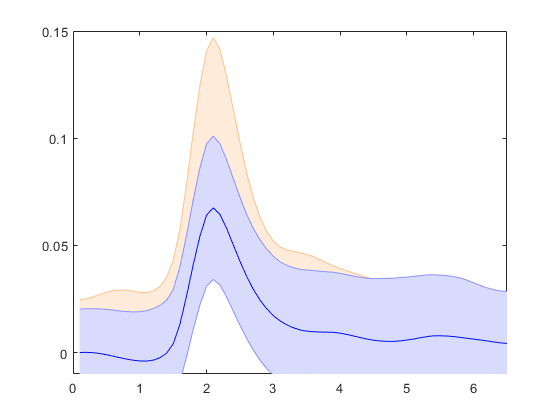

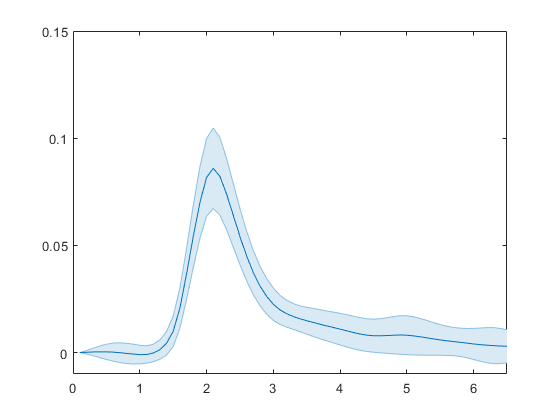

[avgVg3, seVg3m hwVg3, amplVg3] = waveform2(vg3_paths);

    0.0516



   1.3516e-07



   1.8226e-09



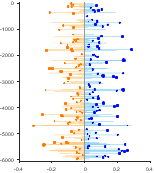

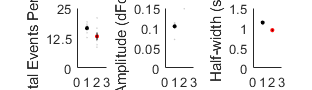


indStats = WTdata;
indStats2 = VG3data;
plotFlag = 1;
 m = size(indStats,1);
    m2 = size(indStats2,1);
    lgrey = [0.8 0.8 0.8];
    markSize = 2;
    meanMarkSize = 10;
    if(plotFlag)
        h = figure;
        
        h.Units = 'inches';
        h.Position = [5 5 6.5/2 1.4/1.5];
        %frequency
        subplot(1,3,1);
            mean1 = mean(indStats.Var7)/10;
            std1 = (std(indStats.Var7)/10)/sqrt(m);
            mean2 = mean(indStats2.Var7)/10;
            std2 = (std(indStats2.Var7)/10)/sqrt(m2);
            scatter(ones(m,1), indStats.Var7/10,markSize,lgrey,'filled');
            hold on;
            scatter(2*ones(m2,1),indStats2.Var7/10,markSize,lgrey,'filled');
            scatter(1,mean1,meanMarkSize,'k','filled');
            scatter(2,mean2,meanMarkSize,'r','filled');
            line([1 2; 1 2], [mean1+std1 mean2+std2; mean1-std1 mean2-std2],'Color','k');
            ylim([0,25]);
            yticks([0 12.5 25]);
            xlim([0 3]);
            %xticklabels({'',cond1,cond2,''});
            ylabel('Total Events Per Min');
            [h, p] = ttest2(indStats.Var7,indStats2.Var7);
            pt(1) = p;
            disp(p);
        %amplitude
        subplot(1,3,2);
            %indMean1 = mean([indStats.meanL indStats.meanR],2);
            %indMean2 = mean([indStats2.meanL indStats2.meanR],2);
            mean1 = mean(ampl);
            std1 = std(ampl)/sqrt(m);
            mean2 = mean(amplVg3);
            std2 = std(amplVg3)/sqrt(m2);
            scatter(ones(m,1), ampl,markSize,lgrey,'filled');
            hold on;
            scatter(2*ones(m2,1), amplVg3,markSize,lgrey,'filled');
            scatter(1,mean1,meanMarkSize,'k','filled');
            scatter(2,mean2,meanMarkSize,'r','filled');
            line([1 2; 1 2], [mean1+std1 mean2+std2; mean1-std1 mean2-std2],'Color','k');
            ylim([0,.15]);
            yticks([0 .05 .10 .15]);
            xlim([0 3]);
            %xticklabels({'',cond1,cond2,''});
            ylabel('Amplitude (dFoF)');
            [h, p] = ttest2(amplVg3,ampl);
            pt(2)=p;
            disp(p);
       subplot(1,3,3);
       mean1 = mean(hw)/10;
            std1 = std(hw)/10/sqrt(m);
            mean2 = mean(hwVg3)/10;
            std2 = std(hwVg3)/10/sqrt(m2);
           scatter(ones(m,1), hw/10,markSize,lgrey,'filled');
           hold on;
           scatter(2*ones(m2,1), hwVg3/10,markSize,lgrey,'filled')';
           scatter(1,mean1,meanMarkSize,'k','filled');
            scatter(2,mean2,meanMarkSize,'r','filled');
            line([1 2; 1 2], [mean1+std1 mean2+std2; mean1-std1 mean2-std2],'Color','k');
           ylim([0 1.5]);
           yticks([0 0.5 1 1.5]);
           xlim([0 3]);
           %xticklabels({'',cond1,cond2,''});
           ylabel('Half-width (s)');
           [h,p] = ttest2(hw,hwVg3);
           pt(5) = p;
           disp(p);
           set(findall(h,'-property','FontSize'),'FontSize',4) 
    end

## VG3 picture example and time course

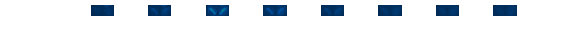

file = 'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-606_Snap25GC6s_vGluT3KO_PCA\Experiment-606_PCA.tif';
%X = loadTif(file,32);
%X = normalizeImg(X,10,1);

%event1
range = [887:912];
points = [range(1):5:range(1)+5*7];
numPts = size(points,2);

h=figure; 
h.Units = 'inches';
h.Position = [5 5 6 0.4];

for i = 1:numPts
    subplot(1,numPts,i);
    imagesc(X(1:end-10,10:end-30,points(i)));
    axis off;
    caxis([-7 50]);
end
colormap gfb;

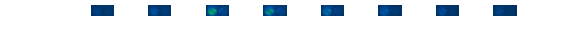


range = [785:785+6*5];
points = [range(1):5:range(1)+5*7];
numPts = size(points,2);
h = figure; 
h.Units = 'inches';
h.Position = [5 5 6 0.4];
for i = 1:numPts
    subplot(1,numPts,i);
    imagesc(imgaussfilt(X(1:end-10,10:end-30,points(i)),1));
    axis off;
    caxis([-15 90]);
end
  colormap gfb;

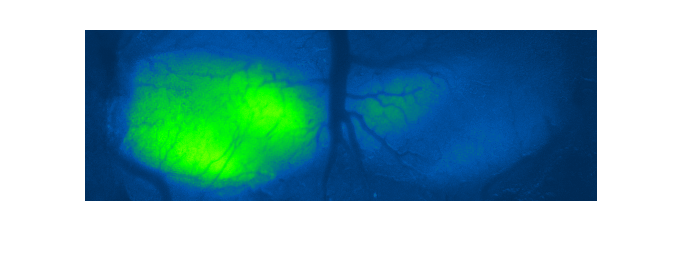


%individual examples
figure;
subplot(3,1,1);
imagesc(X(:,:,points(3)));
colormap gfb;
caxis([-7 50]);
axis off;
truesize;

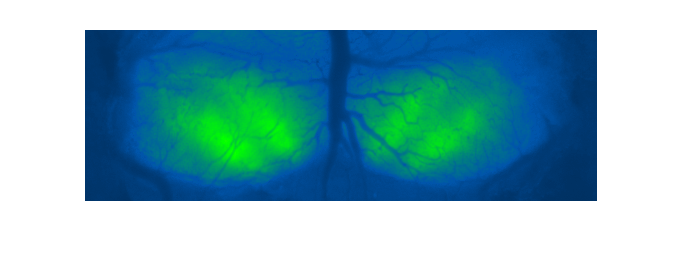

subplot(3,1,2);
imagesc(X(:,:,732));
colormap gfb;
caxis([-15 90]);
axis off;
truesize;

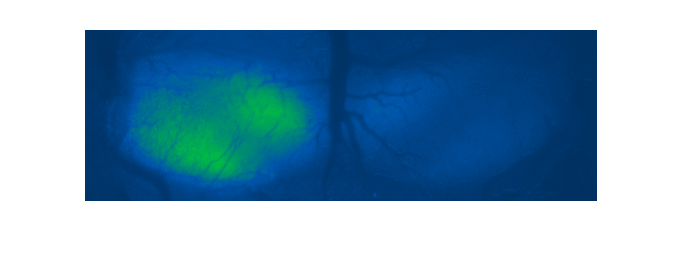

subplot(3,1,2);
imagesc(X(:,:,795));
colormap gfb;
caxis([-15 90]);
axis off;
truesize;

## Histogram compare

event deleted


groupHistoL =     46
    50
    98
    77
    78
    51
    66
    98
    74
    28


groupHistoR =     41
    94
    79
    92
   107
    55
    52
    44
    90
    34


totalEvents = 685×12 table
    eventLabel    eventClassification    leftOrRightDom    numPeaks     domAmp     maxLAmp     maxRAmp     xloc    tloc     hwt       hwx      integral
    __________    ___________________    ______________    ________    ________    ________    ________    ____    ____    ______    ______    ________

      1           'Left'                 'Left'            1            0.27312     0.27312           0     50      247    10.175       NaN    21.805  
      2           'Left'                 'Left'            1           0.059259    0.059259           0     

lhistosing =          0         0         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0    0.0145         0    0.0156    0.0084         0
    0.0154    0.0213    0.0145    0.1333    0.0938    0.1261    0.0746
         0    0.0213    0.0145    0.0133         0    0.0588    0.0597
         0    0.0213    0.0145    0.0400         0    0.0588    0.1343
    0.2000    0.0213    0.0870    0.1200    0.1250    0.1513    0.0448
    0.3692    0.1277    0.0870    0.0933    0.0938    0.1176    0.0746
    0.0769    0.1915    0.2029    0.0800    0.0313    0.0504    0.0373
    0.0923    0.2128    0.2899    0.0267    0.1094    0.0336    0.1119


rhistosing =          0         0         0         0         0         0         0
         0         0         0         0         0         0         0
    0.0114         0    0.0143         0         0         0    0.0143
    0.0341         0    0.0286    0.0845    0.0147    0.0885    0.1429
    0.0227    0.0204    0.0714    0.0563    0.0147    0.1504    0.0500
    0.1023    0.0408    0.0571    0.0563    0.0441         0    0.0357
    0.0682         0    0.1000         0    0.0882    0.0796    0.0643
    0.1250    0.0204    0.1143    0.0704    0.0735    0.0708    0.1786
    0.0455    0.1224    0.1000    0.1268    0.1324    0.2301    0.0929
    0.0341    0.1429    0.1571    0.1549    0.0588    0.0531    0.0214


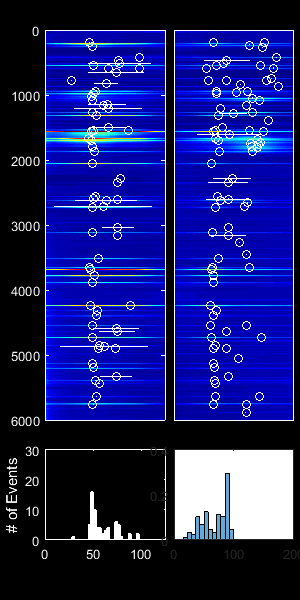

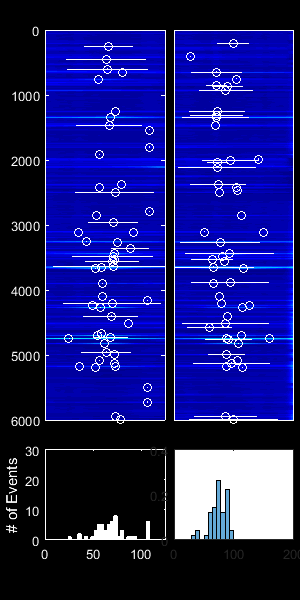

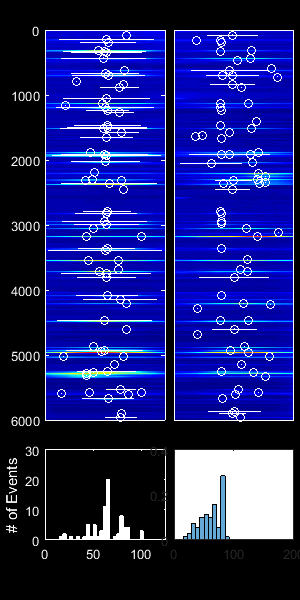

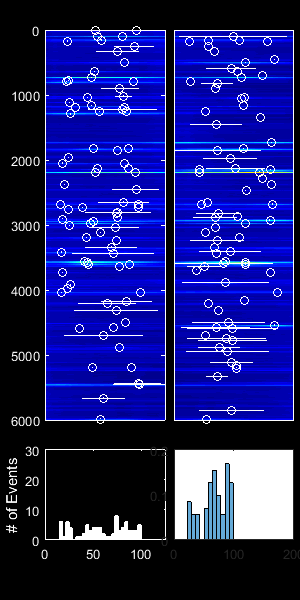

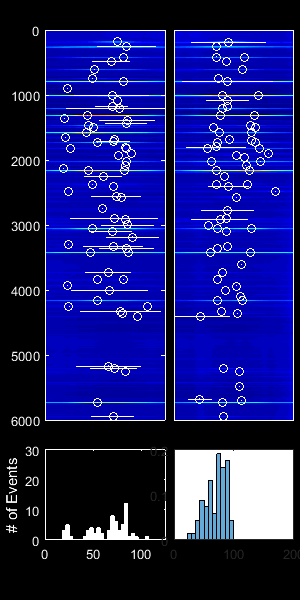

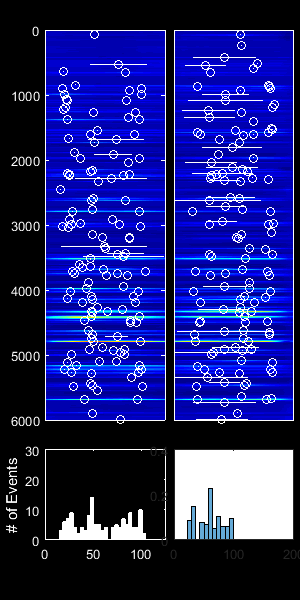

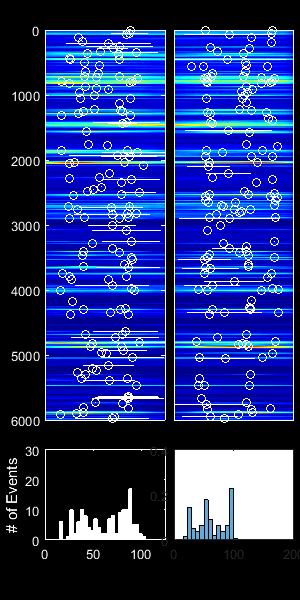

%%load
vg3_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-496-P7-Snap25GC6s_vGluT3_PCA\ICmovs_peaks_dFoF_remflash01.mat';
        'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-545_P8_Snap25GC6s_vGluT3_matreg_PCA\ICmovs_peaks_dFoF_remflash01.mat';
         'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-593-Snap25GC6s_vGluT3KO_PCA\ICmovs_peaks_dFoF_remflash01.mat';
         'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-606_Snap25GC6s_vGluT3KO_PCA\ICmovs_peaks_dFoF_remflash01.mat';
         'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-607_Snap25GC6s_vGluT3KO_PCA\ICmovs_peaks_dFoF_remflash01.mat';
         'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-799_Snap25GC6s_vGluT3KO_reg\ICmovs_peaks_dFoF_remflash01.mat';
         'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\Experiment-974_Snap25GC6s_vGluT3KO\ICmovs_peaks_dFoF_remflash01.mat'
         };
                
[groupHistoL,groupHistoR,totalEvents,~, lhistosing, rhistosing] = analGroupDataLR(vg3_paths,0,'probability')

groupHistoL =     54
    20
    56
    71
    20
    36
    34
    37
    42
    22


groupHistoR =     83
    35
    70
    78
    97
   107
   106
    70
    92
    31


totalEvents = 1344×12 table
    eventLabel    eventClassification    leftOrRightDom    numPeaks     domAmp     maxLAmp     maxRAmp     xloc    tloc     hwt       hwx      integral
    __________    ___________________    ______________    ________    ________    ________    ________    ____    ____    ______    ______    ________

      1           'Left'                 'Left'            1           0.050695    0.050695           0     56       87    9.0505       NaN    3.2731  
      2           'Left'                 'Left'            1           0.073571    0.073571           0    

individualStats =   154.0000    0.1591   14.3373   61.4003   14.2857  104.0000   14.5950   14.1029   63.3611   60.0000    0.1647    0.1487         0         0         0
  185.0000    0.1348   15.3810   54.8973    8.6486  164.0000   13.8754   16.3444   55.5490   54.2353    0.1219    0.1368         0         0         0
  183.0000    0.1324   14.3996   51.0000    7.1038  157.0000   14.5803   14.1931   49.2233   51.6095    0.1265    0.1417         0         0         0
  171.0000    0.1006   13.6337   51.4410    5.2632  132.0000   13.0000   14.3663   51.4410   51.5705    0.1012    0.1004         0         0         0
  199.0000    0.1240   14.2221   46.6040    8.0402  171.0000   14.1047   14.4604   50.3701   43.5987    0.1219    0.1260         0         0         0
  150.0000    0.1539   14.3018   51.9506   14.6667  122.0000   14.9890   13.7503   49.0000   52.0609    0.1381    0.1647         0         0         0
  147.0000    0.1627   14.8037   52.1323   11.5646  124.0000   15.0195   14.

lhistosing =          0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
    0.0093    0.0156    0.0075    0.0085    0.0070    0.0080    0.0261    0.0085
    0.0935    0.0781    0.1203    0.0940    0.0634    0.1120    0.0609    0.1271
    0.1308    0.0859    0.0977    0.1026    0.1197    0.0960    0.0783    0.0932
    0.1402    0.0859    0.0827    0.0769    0.0704    0.1120    0.0783    0.0593
    0.1028    0.1172    0.0827    0.0940    0.1197    0.1360    0.1217    0.1102
    0.0841    0.1094    0.1278    0.1538    0.1549    0.1120    0.1391    0.0678
    0.0654    0.1250    0.0977    0.1111    0.1127    0.0960    0.1304    0.1356
    0.0748    0.1016    0.1203    0.0855    0.0845    0.0640    0.1130    0.0932


rhistosing =          0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
    0.0185         0         0         0         0         0         0    0.0099
    0.1111    0.0376    0.1481    0.0403    0.0455    0.0357    0.0297    0.1089
    0.1204    0.0752    0.0222    0.1129    0.0530    0.0268    0.1485    0.0891
    0.1481    0.0977    0.0444    0.1210    0.0682    0.1429    0.0891    0.1386
    0.1019    0.0977    0.0667    0.1048    0.0833    0.1429    0.0891    0.0792
    0.1111    0.0827    0.1704    0.1452    0.1591    0.1429    0.1386    0.0594
    0.1019    0.1203    0.1037    0.1210    0.0985    0.0893    0.1089    0.0792
    0.0648    0.0827    0.0963    0.1210    0.1288    0.1607    0.0891    0.0891


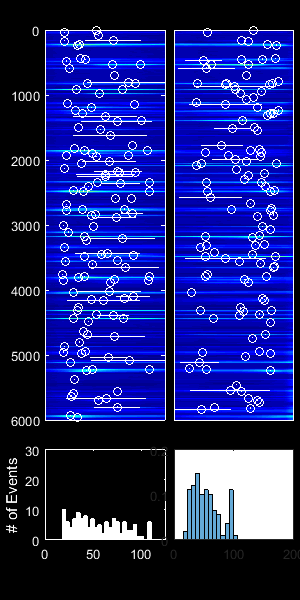

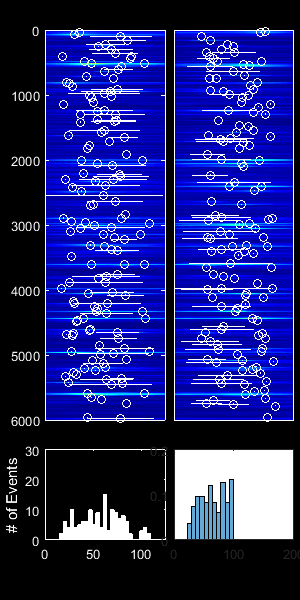

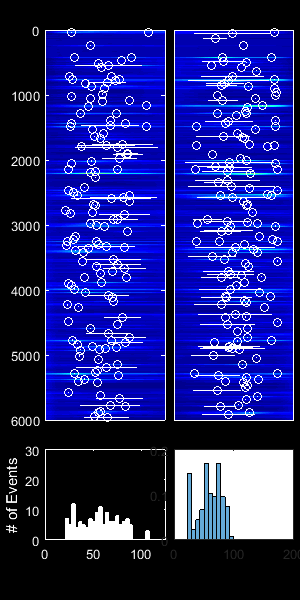

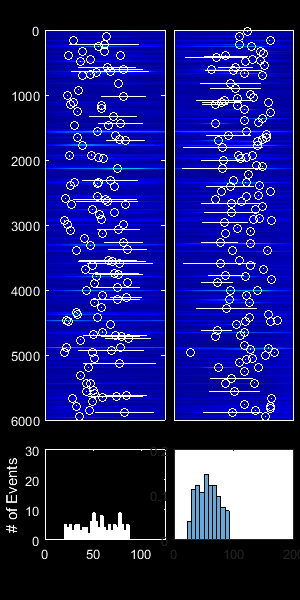

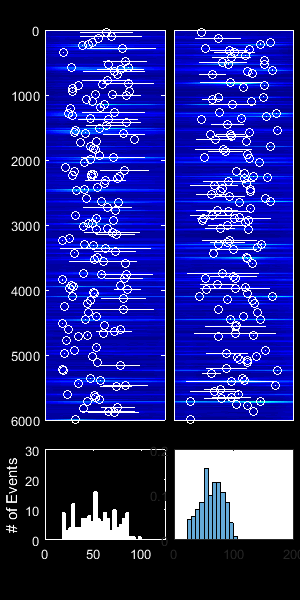

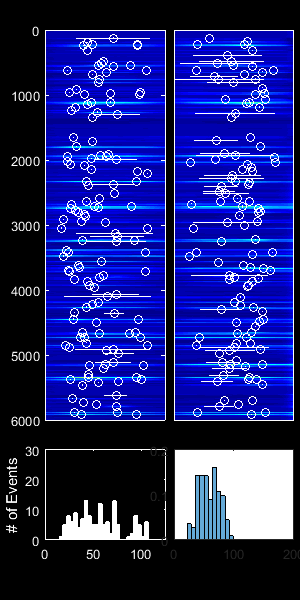

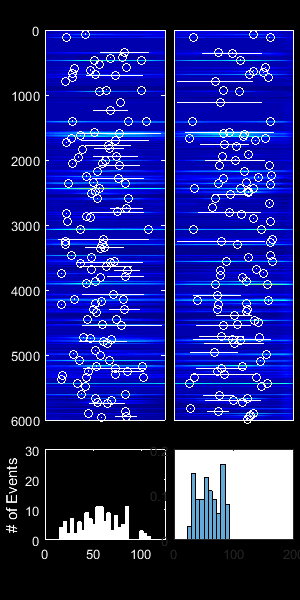

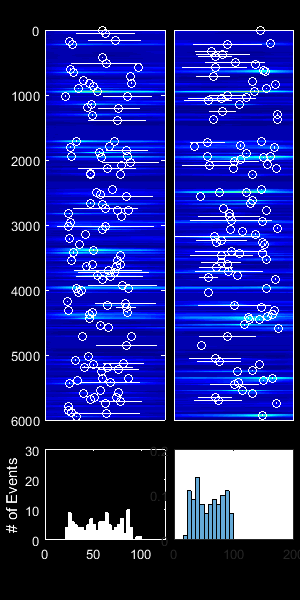

lcounts = mean(lhistosing,2);
rcounts = mean(rhistosing,2);
lcountserr = std(lhistosing,1,2)/sqrt(size(lhistosing,2));
rcountserr = std(rhistosing,1,2)/sqrt(size(rhistosing,2));
vg3_histo_ind = (lhistosing + rhistosing)/2;
vg3_histo = mean(vg3_histo_ind,2);
vg3_histoerr = std(vg3_histo_ind,1,2)/sqrt(size(vg3_histo_ind,2));

wt_paths = {%'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-265-P7_Wildtype_PCA\ICmovs_peaks_dFoF_remflash.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-314-P6_Wildtype_PCA\ICmovs_peaks_dFoF_remflash.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-330_processed\ICmovs_peaks_dFoF_remflash.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-337-ds_PCApro\ICmovs_peaks_dFoF_remflash.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-342_P2ry1het_ds.tif_PCA\ICmovs_peaks_dFoF_remflash.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-495-P7-Snap25GC6s_Wildtype_PCA\ICmovs_peaks_dFoF_remflash.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-569_P6-Snap25GC6s_PCA\ICmovs_peaks_dFoF_remflash.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-571_P6-Snap25GC6s_PCA\ICmovs_peaks_dFoF_remflash.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\Experiment-974_Snap25GC6s_vGluT3het\ICmovs_peaks_dFoF_remflash.mat'
};

[groupHistoL,groupHistoR,totalEvents,individualStats, lhistosing, rhistosing] = analGroupDataLR(wt_paths,0,'probability')

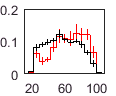

 lcounts = mean(lhistosing,2);
rcounts = mean(rhistosing,2);
lcountserr = std(lhistosing,1,2)/sqrt(size(lhistosing,2));
rcountserr = std(rhistosing,1,2)/sqrt(size(rhistosing,2));
wt_histo_ind = (lhistosing + rhistosing)/2;
wt_histo = mean(wt_histo_ind,2);
wt_histoerr = std(wt_histo_ind,1,2)/sqrt(size(wt_histo_ind,2));
    
edges = 1:7:125;
edgesX = 4.5:7:120;
shift = 0;
h = figure;
h.Units = 'inches';
h.Position = [5 5 (4/4)*.8 (3/3)*1];
histogram('BinEdges',edges+shift,'BinCounts',vg3_histo,'EdgeColor','r','FaceColor','none','DisplayStyle','stairs','FaceAlpha',1); hold on;
histogram('BinEdges',edges,'BinCounts',wt_histo,'EdgeColor','k','FaceColor','none','DisplayStyle','stairs','FaceAlpha',1);
line([edgesX+shift; edgesX+shift],[vg3_histo' + vg3_histoerr';vg3_histo' - vg3_histoerr'],'Color','r');
line([edgesX; edgesX],[wt_histo' + wt_histoerr';wt_histo' - wt_histoerr'],'Color','k');
xlim([10 110])

## Group Data

## Compare WT, Labl, Rabl, Bil abl, NBQX

WT_avg = mean(WT_stats{:,:},1)/10;
WT_std = std(WT_stats{:,:},1)/10;
rabl_avg = mean(rabl_stats{:,:},1)/10;
rabl_std = std(rabl_stats{:,:},1)/10;
labl_avg = mean(labl_stats{:,:},1)/10;
labl_std = std(labl_stats{:,:},1)/10;
bilabl_avg = mean(bilabl_stats{:,:},1)/10;
bilabl_std = std(bilabl_stats{:,:},1)/10;
%NBQX_avg = mean(NBQX_stats{:,:},1)/10;
%NBQX_std = std(NBQX_stats{:,:},1)/10;

 lt_org = [255, 166 , 38]/255;
 dk_org = [255, 120, 0]/255;
 lt_blue = [50, 175, 242]/255;
 dk_blue = [0, 13, 242]/255;
 gray = [0.7 0.7 0.7];
 

%pull leftdom and rightdom individual
WT_dom = WT_stats{:,8:9}';
WT_n = size(WT_dom,2);
rabl_dom = rabl_stats{:,8:9}';
r_n = size(rabl_dom,2);
labl_dom = labl_stats{:,8:9}';
l_n = size(labl_dom,2);
bilabl_dom = bilabl_stats{:,8:9}';
b_n = size(bilabl_dom,2);
% NBQX_dom = NBQX_stats{:,8:9}';
% NBQX_n = size(NBQX_dom,2);

mk_size = 14;
figh = figure;
line([ones(1,WT_n); 2*ones(1,WT_n)],[WT_dom(1,:)/10; WT_dom(2,:)/10],'Color',gray); hold on;
line([1 2], WT_avg(:,8:9),'Color','k');
line([1; 1], [WT_avg(1,8) + WT_std(8); WT_avg(1,8) - WT_std(8)],'Color',lt_org,'LineWidth',1);
line([2; 2], [WT_avg(1,9) + WT_std(9); WT_avg(1,9) - WT_std(9)],'Color',lt_blue,'LineWidth',1);
plot(1, WT_avg(:,8),'.','MarkerSize',mk_size,'Color',lt_org);
plot(2, WT_avg(:,9),'.','MarkerSize',mk_size,'Color',lt_blue);

line([3*ones(1,r_n); 4*ones(1,r_n)],[rabl_dom(1,:)/10; rabl_dom(2,:)/10],'Color',gray);
line([3 4], rabl_avg(:,8:9),'Color','k');
line([3; 3], [rabl_avg(1,8) + rabl_std(8); rabl_avg(1,8) - rabl_std(8)],'Color',lt_org,'LineWidth',1);
line([4; 4], [rabl_avg(1,9) + rabl_std(9); rabl_avg(1,9) - rabl_std(9)],'Color',lt_blue,'LineWidth',1);
plot(3, rabl_avg(:,8),'.','MarkerSize',mk_size,'Color',lt_org);
plot(4, rabl_avg(:,9),'.','MarkerSize',mk_size,'Color',lt_blue);

line([5*ones(1,l_n); 6*ones(1,l_n)],[labl_dom(1,:)/10; labl_dom(2,:)/10],'Color',gray);
line([5 6], labl_avg(:,8:9),'Color','k');
line([5; 5], [labl_avg(1,8) + labl_std(8); labl_avg(1,8) - labl_std(8)],'Color',lt_org,'LineWidth',1);
line([6; 6], [labl_avg(1,9) + labl_std(9); labl_avg(1,9) - labl_std(9)],'Color',lt_blue,'LineWidth',1);
plot([5], labl_avg(:,8),'.','MarkerSize',mk_size,'Color',lt_org);
plot(6, labl_avg(:,9),'.','MarkerSize',mk_size,'Color',lt_blue);

line([7*ones(1,b_n); 8*ones(1,b_n)],[bilabl_dom(1,:)/10; bilabl_dom(2,:)/10],'Color',gray);
line([7 8], bilabl_avg(:,8:9),'Color','k');
line([7; 7], [bilabl_avg(1,8) + bilabl_std(8); bilabl_avg(1,8) - bilabl_std(8)],'Color',lt_org,'LineWidth',1);
line([8; 8], [bilabl_avg(1,9) + bilabl_std(9); bilabl_avg(1,9) - bilabl_std(9)],'Color',lt_blue,'LineWidth',1);
plot(7, bilabl_avg(:,8),'.','MarkerSize',mk_size,'Color',lt_org);
plot(8, bilabl_avg(:,9),'.','MarkerSize',mk_size,'Color',lt_blue);

% % line([9*ones(1,NBQX_n); 10*ones(1,NBQX_n)],[NBQX_dom(1,:)/10; NBQX_dom(2,:)/10],'Color',gray);
% % line([9 10], NBQX_avg(:,8:9),'Color','k');
% % line([9; 9], [NBQX_avg(1,8) + NBQX_std(8); NBQX_avg(1,8) - NBQX_std(8)],'Color',lt_org,'LineWidth',1);
% % line([10; 10], [NBQX_avg(1,9) + NBQX_std(9); NBQX_avg(1,9) - NBQX_std(9)],'Color',lt_blue,'LineWidth',1);
% % plot(9, NBQX_avg(:,8),'.','MarkerSize',mk_size,'Color',lt_org);
% % plot(10, NBQX_avg(:,9),'.','MarkerSize',mk_size,'Color',lt_blue);

xlim([0.5 8.5]);
xticks([1:1:8]);
xticklabels(repmat({'L' 'R'},1,5));
xlabel('Place Holder');
ylim([0 18]);
yticks([0 6 12 18]);
axh = gca;
dim = [2.75 1];
figQuality(figh, axh, dim);
ylabel('Dominant events per min','FontSize',8);
export_fig(['.\EPS Panels\group_DomEvents.eps'], '-eps', '-nocrop')

%pull leftdom and rightdom total events (not dominant
WT_dom = WT_stats{:,1:2}';
WT_n = size(WT_dom,2);
rabl_dom = rabl_stats{:,1:2}';
r_n = size(rabl_dom,2);
labl_dom = labl_stats{:,1:2}';
l_n = size(labl_dom,2);
bilabl_dom = bilabl_stats{:,1:2}';
b_n = size(bilabl_dom,2);
% NBQX_dom = NBQX_stats{:,1:2}';
% NBQX_n = size(NBQX_dom,2);

figi = figure;
line([ones(1,WT_n); 2*ones(1,WT_n)],[WT_dom(1,:)/10; WT_dom(2,:)/10],'Color',gray); hold on;
line([1 2], WT_avg(:,1:2),'Color','k');
line([1; 1], [WT_avg(1,1) + WT_std(1); WT_avg(1,1) - WT_std(1)],'Color',lt_org,'LineWidth',1);
line([2; 2], [WT_avg(1,2) + WT_std(2); WT_avg(1,2) - WT_std(2)],'Color',lt_blue,'LineWidth',1);
plot([1], WT_avg(:,1),'.','MarkerSize',mk_size,'Color',lt_org);
plot([2], WT_avg(:,2),'.','MarkerSize',mk_size,'Color',lt_blue);

line([3*ones(1,r_n); 4*ones(1,r_n)],[rabl_dom(1,:)/10; rabl_dom(2,:)/10],'Color',gray);
line([3 4], rabl_avg(:,1:2),'Color','k');
line([3; 3], [rabl_avg(1,1) + rabl_std(1); rabl_avg(1,1) - rabl_std(1)],'Color',lt_org,'LineWidth',1);
line([4; 4], [rabl_avg(1,2) + rabl_std(2); rabl_avg(1,2) - rabl_std(2)],'Color',lt_blue,'LineWidth',1);
plot([3], rabl_avg(:,1),'.','MarkerSize',mk_size,'Color',lt_org);
plot([4], rabl_avg(:,2),'.','MarkerSize',mk_size,'Color',lt_blue);

line([5*ones(1,l_n); 6*ones(1,l_n)],[labl_dom(1,:)/10; labl_dom(2,:)/10],'Color',gray);
line([5 6], labl_avg(:,1:2),'Color','k');
line([5; 5], [labl_avg(1,1) + labl_std(1); labl_avg(1,1) - labl_std(1)],'Color',lt_org,'LineWidth',1);
line([6; 6], [labl_avg(1,2) + labl_std(2); labl_avg(1,2) - labl_std(2)],'Color',lt_blue,'LineWidth',1);
plot([5], labl_avg(:,1),'.','MarkerSize',mk_size,'Color',lt_org);
plot([6], labl_avg(:,2),'.','MarkerSize',mk_size,'Color',lt_blue);

line([7*ones(1,b_n); 8*ones(1,b_n)],[bilabl_dom(1,:)/10; bilabl_dom(2,:)/10],'Color',gray);
line([7 8], bilabl_avg(:,1:2),'Color','k');
line([7; 7], [bilabl_avg(1,1) + bilabl_std(1); bilabl_avg(1,1) - bilabl_std(1)],'Color',lt_org,'LineWidth',1);
line([8; 8], [bilabl_avg(1,2) + bilabl_std(2); bilabl_avg(1,2) - bilabl_std(2)],'Color',lt_blue,'LineWidth',1);
plot([7], bilabl_avg(:,1),'.','MarkerSize',mk_size,'Color',lt_org);
plot([8], bilabl_avg(:,2),'.','MarkerSize',mk_size,'Color',lt_blue);

% line([9*ones(1,NBQX_n); 10*ones(1,NBQX_n)],[NBQX_dom(1,:)/10; NBQX_dom(2,:)/10],'Color',gray);
% line([9 10], NBQX_avg(:,1:2),'Color','k');
% line([9; 9], [NBQX_avg(1,1) + NBQX_std(1); NBQX_avg(1,1) - NBQX_std(1)],'Color',lt_org,'LineWidth',1);
% line([10; 10], [NBQX_avg(1,2) + NBQX_std(2); NBQX_avg(1,2) - NBQX_std(2)],'Color',lt_blue,'LineWidth',1);
% plot([9], NBQX_avg(:,1),'.','MarkerSize',mk_size,'Color',lt_org);
% plot([10], NBQX_avg(:,2),'.','MarkerSize',mk_size,'Color',lt_blue);


xlim([0.5 8.5]);
xticks([1:1:8]);
xticklabels(repmat({'L' 'R'},1,5));
ylim([0 18]);
yticks([0 6 12 18]);
xlabel('Place Holder');
axh = gca;
dim = [2.75 1];
figQuality(gcf, axh, dim);
ylabel('Events per min','FontSize',8);
export_fig(['.\EPS Panels\group_TotEvents.eps'], '-eps', '-nocrop')
